clear variables;
%% parameters Setting
% Start clock
initClock = clock;
% Input parameters Setting
workingMode = 1;            % 1: K-mesh at xy plane;  2: K-path at high-symmetry path
fermiLevel = -2.4474445;    % Should be defined in K-path Working Mode
fittingNeighbourOrder = 10;  % Fitting Order
initialHoppingParameterDataBase = [-2.430432, -0.040101, 0.097522, -0.070591, 0.0176250, -0.027414, 0.0046590, 0.001030, -0.010559, 0.000786, ...
    0.006749, -0.009858, 0.002722, -0.001447, 0.005350, -0.004718, 0.000434, 0.000423, 0.002563, 0.001689];
initialHoppingParameter = initialHoppingParameterDataBase(1: fittingNeighbourOrder);
%% Initialize fitting function (DO NOT EDIT THIS SECTION)
% Lattice Construction
a1 = [3.3291   -0.0000    0.0000];
a2 = [-1.6645    2.8831   -0.0000];
a3 = [0.0000   -0.0000   23.1180];
% Hopping Matrix & Hopping Parameter Construction
hoppingMatrix{1} = [0, 0, 0];
hoppingMatrix{2} = [-1, 0, 0; -1, -1, 0; 0, 1, 0; 0, -1, 0; 1, 1, 0; 1, 0, 0];
hoppingMatrix{3} = [-2, -1, 0; -1, 1, 0; -1, -2, 0; 1, 2, 0; 1, -1, 0; 2, 1, 0];
hoppingMatrix{4} = [-2, 0, 0; -2, -2, 0; 0, 2, 0; 0, -2, 0; 2, 2, 0; 2, 0, 0];
hoppingMatrix{5} = [-3,-1,0;-3,-2,0;-2,1,0;-2,-3,0;-1,2,0;-1,-3,0;1,3,0;1,-2,0;2,3,0;2,-1,0;3,2,0;3,1,0];
hoppingMatrix{6} = [-3,0,0;-3,-3,0;0,3,0;0,-3,0;3,3,0;3,0,0];
hoppingMatrix{7} = [-4,-2,0;-2,2,0;-2,-4,0;2,4,0;2,-2,0;4,2,0];
hoppingMatrix{8} = [-4,-1,0;-4,-3,0;-3,1,0;-3,-4,0;-1,3,0;-1,-4,0;1,4,0;1,-3,0;3,4,0;3,-1,0;4,3,0;4,1,0];
hoppingMatrix{9} = [-4,0,0;-4,-4,0;0,4,0;0,-4,0;4,4,0;4,0,0];
hoppingMatrix{10}= [-5,-2,0;-5,-3,0;-3,2,0;-3,-5,0;-2,3,0;-2,-5,0;2,5,0;2,-3,0;3,5,0;3,-2,0;5,3,0;5,2,0];
hoppingMatrix{11}= [-5,-1,0;-5,-4,0;-4,1,0;-4,-5,0;-1,4,0;-1,-5,0;1,5,0;1,-4,0;4,5,0;4,-1,0;5,4,0;5,1,0];
hoppingMatrix{12}=[-5,0,0;-5,-5,0;0,5,0;0,-5,0;5,5,0;5,0,0];
hoppingMatrix{13}=[-6,-3,0;-3,3,0;-3,-6,0;3,6,0;3,-3,0;6,3,0];
hoppingMatrix{14}=[-6,-2,0;-6,-4,0;-4,2,0;-4,-6,0;-2,4,0;-2,-6,0;2,6,0;2,-4,0;4,6,0;4,-2,0;6,4,0;6,2,0];
hoppingMatrix{15}=[-6,-1,0;-6,-5,0;-5,1,0;-5,-6,0;-1,5,0;-1,-6,0;1,6,0;1,-5,0;5,6,0;5,-1,0;6,5,0;6,1,0];
hoppingMatrix{16}=[-6,0,0;-6,-6,0;0,6,0;0,-6,0;6,6,0;6,0,0];
hoppingMatrix{17}=[-7,-3,0;-7,-4,0;-4,3,0;-4,-7,0;-3,4,0;-3,-7,0;3,7,0;3,-4,0;4,7,0;4,-3,0;7,4,0;7,3,0];
hoppingMatrix{18}=[-7,-2,0;-7,-5,0;-5,2,0;-5,-7,0;-2,5,0;-2,-7,0;2,7,0;2,-5,0;5,7,0;5,-2,0;7,5,0;7,2,0];
hoppingMatrix{19}=[-7,-1,0;-7,-6,0;-6,1,0;-6,-7,0;-1,6,0;-1,-7,0;1,7,0;1,-6,0;6,7,0;6,-1,0;7,6,0;7,1,0];
hoppingMatrix{20}=[-8,-4,0;-4,4,0;-4,-8,0;4,8,0;4,-4,0;8,4,0];
hoppingParameter{1} = -2.430432;
hoppingParameter{2} = -0.0401010000000000;
hoppingParameter{3} = 0.0975220000000000;
hoppingParameter{4} = -0.0705910000000000;
hoppingParameter{5} = 0.0176250000000000;
hoppingParameter{6} = -0.0274140000000000;
hoppingParameter{7} = 0.00465900000000000;
hoppingParameter{8} = 0.00103000000000000;
hoppingParameter{9} = -0.0105590000000000;
hoppingParameter{10}= 0.000786000000000000;
hoppingParameter{11}= 0.00674900000000000;
hoppingParameter{12}= -0.00985800000000000;
hoppingParameter{13}= 0.00272200000000000;
hoppingParameter{14}= -0.00144700000000000;
hoppingParameter{15}= 0.00535000000000000;
hoppingParameter{16}= -0.00471800000000000;
hoppingParameter{17}= 0.000434000000000000;
hoppingParameter{18}= 0.000423000000000000;
hoppingParameter{19}= 0.00256300000000000;
hoppingParameter{20}= 0.00168900000000000;

% Lattice data Processing
transMatA = [a1;a2;a3];
V = dot(a1, cross(a2, a3));
b1 = 2*pi*cross(a2,a3)/V;
b2 = 2*pi*cross(a3,a1)/V;
b3 = 2*pi*cross(a1,a2)/V;
transMatB = [b1;b2;b3];

if workingMode == 2
% Generates K-Path (Path Working Mode)
    kpoints{1} = [0 0 0]* transMatB;
    kpoints{2} = [0 0.5 0]* transMatB;
    kpoints{3} = [-0.3333 0.6667 0.0]* transMatB;
    kpoints{4} = [0 0 0]* transMatB;
    Ntot = 51;
    for loopIndex = 1: length(kpoints) - 1
        kPointsMesh(Ntot*(loopIndex - 1) + 1: Ntot* loopIndex, 1: 3) = [linspace(kpoints{loopIndex}(1), kpoints{loopIndex + 1}(1), Ntot)', linspace(kpoints{loopIndex}(2), kpoints{loopIndex + 1}(2), Ntot)', ...
            linspace(kpoints{loopIndex}(3), kpoints{loopIndex + 1}(3), Ntot)'];
    end
    numIdx = Ntot: Ntot:(length(kpoints) - 2)*Ntot;
    kPointsMesh(numIdx, :) = [];
    kPathDistance = 0;
    kPointsMesh(1, 4) = 0;
    for loopIndex = 2: length(kPointsMesh)
        sqrtPart(1) = (kPointsMesh(loopIndex, 1) - kPointsMesh(loopIndex - 1, 1));
        sqrtPart(2) = (kPointsMesh(loopIndex, 2) - kPointsMesh(loopIndex - 1, 2));
        sqrtPart(3) = (kPointsMesh(loopIndex, 3) - kPointsMesh(loopIndex - 1, 3));
        kPathDistance = kPathDistance + sqrt(sqrtPart(1)^2 + sqrtPart(2)^2 + sqrtPart(3)^2 );
        kPointsMesh(loopIndex, 4) = kPathDistance;
    end
    kPointsMesh = kPointsMesh';
    load('wannier90_band.dat');
    % Interpolante the wannier fitting results for calculating difference.
    interpGrid = griddedInterpolant(wannier90_band(:, 1), wannier90_band(:, 2), 'linear');
    targetHkin = interpGrid(kPointsMesh(4, :)) - fermiLevel;
else
% OR import K-mesh (Plane Working Mode)
     load('savedFigureData.mat');
     selectionIndex = ~isnan(exportData.bandStructure_3D.bandeigenvalueSelected);
     kPointsMesh = exportData.hubbardModel.kpointsRecipMeshSelected(1:3, selectionIndex);
     targetHkin = exportData.hubbardModel.bandeigenvalueSelected(selectionIndex);
end

Function Fitting (Solver should be placed in this section)

Here is an illustration about setting the solver

Target Function: (x, y, F(x, y))

For workingMode = 1:  Target Function:    x             -> kPointsMesh(1, :)',

                                                                   y             -> kPointsMesh(2, :)'

                                                                   F(x, y)     -> targetHkin 

                                       Fitting Function:   x             -> kPointsMesh(1, :)',

                                                                    y            -> kPointsMesh(2, :)'

                                                                    F(x, y)     -> Hkin

For workingMode = 2:  Target Function:    x              -> kPointsMesh(4, :)',

                                                                    F(x)        -> targetHkin 

                      Fitting Function:                     x            -> kPointsMesh(4, :)',

                                                                    F(x)        -> Hkin

## Initialize solver

Solver-based Optimizer

switch workingMode
    case 1
        f = @(t)calculateTargetFunction(workingMode, transMatA, kPointsMesh, t, hoppingMatrix, exportData.fermiLevel, targetHkin);
    case 2
        f = @(t)calculateTargetFunction(workingMode, transMatA, kPointsMesh, t, hoppingMatrix, fermiLevel, targetHkin);
end

- Create Problem, Linear Constrains, and Solution (Without constrain)

Starting parallel pool (parpool) using the 'local' profile ...

     2         492        0.0487607        1.19109           6.47  


     3         533        0.0471402              1           5.12  


     4         574        0.0470054              1           11.1  


     5         656        0.0465021       0.406518            4.6  


     6         820        0.0459356       0.305169           4.25  


     7         984        0.0459251     0.00782083            2.4  



Computing finite-difference Hessian using objective function.


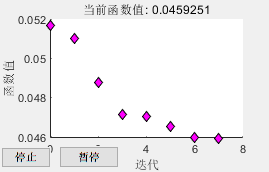


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


fminuncOptions = optimoptions('fminunc', "Algorithm","quasi-Newton", "MaxIterations", 1000,...
    "PlotFcn","optimplotfval", "Display","iter",'FunctionTolerance',1e-9,...
    "MaxFunctionEvaluations", 4000, "UseParallel",true, "FiniteDifferenceType", 'central');
fminsearchOptions = optimset('Display', 'iter', 'FunValCheck', 'on', 'PlotFcns', @optimplotfval);
[x,fval,exitflag,output,grad,hessian] = fminunc(f, initialHoppingParameter, fminuncOptions);

% [x,fval,exitflag,output] = fminsearch(f, initialHoppingParameter, fminsearchOptions);

- Create Problem, Linear Constrains, and Solution (With constrain)

% load("constrain.mat");
% constrainNumber = 1;
% Aeq = [];
% for constrainIndex = 1: constrainNumber
%     Aeq = [Aeq; constrain{constrainIndex}(1: length(initialHoppingParameter))];
% end
% % Aeq = [1     6     6     6    12     6     6    12     6    12; ...
% %      1    -2    -2     6    -4    -2     6    -4     6    -4; ...
% %      1    -3     6    -3    -6     6     6    -6    -3    -6];
% % Aeq = [1     6     6     6    12     6     6    12     6    12];
% 
% switch constrainNumber
%     case 1
%         beq = real(targetHkin(1)) + fermiLevel;
%     case 3
%         beq = [real(targetHkin(1)), real(targetHkin(51)), real(targetHkin(101))] + fermiLevel;
% end
% A = [];
% b = [];
% lb = [];
% ub = [];
% nonlcon = [];
% fminconOptions = optimoptions("fmincon","Algorithm","interior-point","Display","iter",...
%     "PlotFcn","optimplotfval","UseParallel",true, "FiniteDifferenceType", 'central');
% [x,fval,exitflag,output] = fmincon(f, initialHoppingParameter, A, b, Aeq, beq, lb, ub, nonlcon, fminconOptions);

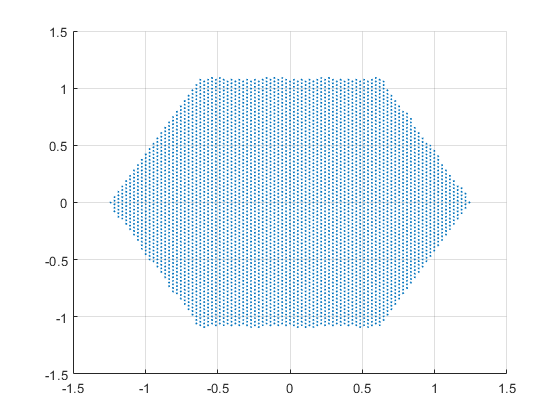


% Visualize the calulate result, uncomment if you need
updatedHoppingParameter = num2cell(x);
calcHkin = zeros(1, length(kPointsMesh));
initHkin = zeros(1, length(kPointsMesh));
for loopIndex = 1:length(kPointsMesh)
    calcHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', updatedHoppingParameter, hoppingMatrix);
    initHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', hoppingParameter, hoppingMatrix);
end

switch workingMode    
    case 1
        diff = calculateDifference(1, kPointsMesh(1, :)', fermiLevel ,calcHkin, targetHkin);
        figure();
        scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(calcHkin) - exportData.fermiLevel, 1);
        figure();
        scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(diff), 1);
    case 2
        diff = calculateDifference(1, kPointsMesh(4, :)', fermiLevel ,calcHkin, targetHkin);
        figure();
        plot(kPointsMesh(4, :), real(calcHkin) - fermiLevel, 'b');
        hold on;
        plot(kPointsMesh(4, :), real(targetHkin), 'r');
        plot(kPointsMesh(4, :), real(initHkin) - fermiLevel, 'k--');
        legend(["Calculate", "Target", "Initial"]);
        hold off;
end

FinClock = clock;
timeDuration = etime(FinClock, initClock)

timeDuration = 5.0995e+03

% Export the updated hopping parameter
fileId = fopen(join(['.\summary\', join(string(FinClock(1: 5)),""), '.dat'], ""), "w");
for numIdx = 1: length(updatedHoppingParameter)
    fprintf(fileId, "%12.6f", updatedHoppingParameter{numIdx});
end
fclose(fileId);

## External Function

function Hkin = calculateKineticHamiltonian(transMat, kpointsRecip, hoppingParameter, hoppingMatrixProcessed)
Hkin = 0;
for hoppingOrder = 1: length(hoppingParameter)
    sum = 0;
    hoppingLength = length(hoppingMatrixProcessed{hoppingOrder}(:, 1));
    a1part = cell(1, hoppingLength);
    a2part = cell(1, hoppingLength);
    a3part = cell(1, hoppingLength);
    dotpart = zeros(1, hoppingLength);
    for numIdx = 1: hoppingLength
        a1part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 1).*transMat(1, :);
        a2part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 2).*transMat(2, :);
        a3part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 3).*transMat(3, :);
        dotpart(numIdx) = dot(kpointsRecip, a1part{numIdx} + a2part{numIdx} + a3part{numIdx});
        sum = sum + exp(1i*dotpart(numIdx));
    end
    Hkin = Hkin + hoppingParameter{hoppingOrder}*sum;
end
end

% This calculateDifference function can be customized depending on your
% fitting error method.
function diff = calculateDifference(workingMode, kpointsRecip, fermiLevel ,calcHkin, targetHkin)
difference = zeros(1, length(kpointsRecip));
for loopIndex = 1: length(kpointsRecip)
    difference(loopIndex) = calcHkin(loopIndex) - fermiLevel - targetHkin(loopIndex);
end

switch workingMode
    case 1
        diff = real(difference);
    case 2
        [~, maxIdx] = max(abs(difference));
        diff = real(difference(maxIdx));
    case 3
        diff = mean(real(difference));
    case 4
        diff = var(real(difference));
end
end

function fittingDifference = calculateTargetFunction(workingMode, transMatA, kPointsMesh, hoppingParameter, hoppingMatrix, fermiLevel, targetHkin)
calcDiffMethod = 2;
hoppingParameterCell = num2cell(hoppingParameter);
Hkin = zeros(1, length(kPointsMesh));
for loopIndex = 1:length(kPointsMesh)
    Hkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', hoppingParameterCell, hoppingMatrix);
end
switch workingMode
    case 1
        diff = calculateDifference(calcDiffMethod, kPointsMesh(1, :)', fermiLevel, Hkin, targetHkin);
        fittingDifference = abs(diff);
    case 2
        diff = calculateDifference(calcDiffMethod, kPointsMesh(4, :)', fermiLevel, Hkin, targetHkin);
        fittingDifference = abs(diff);
end
end